## Assignment 6: **Collection and Processing of Electromyography Data**

### 1) Import EMG data

data = readtable('FDI-1.txt');

ASCII values using Biometrics’ SX230 Active EMG Probe. Using the default settings for EMG within the analogue set up dialog box, +/- 4000 counts equals +/- 3 mVdc e.g. an ASCII value of +3000 equates to a muscle signal of (3000/4000)*3 mVdc = + 2.25 mVdc.

EMG_1_raw = (data.Var1)/4000*3;

Specify sampling rate and duration of the recording

Fs = 1000;
t = 1/Fs:1/Fs:length(EMG_1_raw)/Fs

t =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


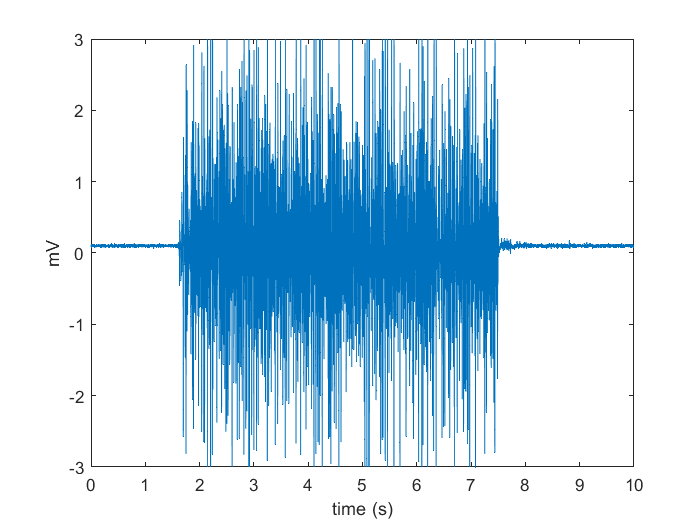


plot(t,EMG_1_raw)
xlabel('time (s)')
ylabel('mV')

Remove signal offset

offset = mean(EMG_1_raw(1:1600))

offset = 0.1014

EMG_1_raw_off = EMG_1_raw-offset

EMG_1_raw_off =     0.0126
   -0.0047
   -0.0017
   -0.0189
   -0.0114
   -0.0249
   -0.0137
   -0.0174
   -0.0099
   -0.0047


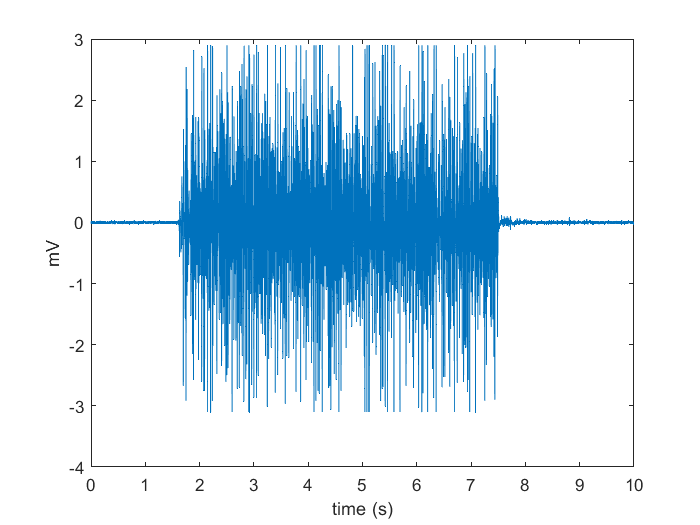


plot(t,EMG_1_raw_off)
xlabel('time (s)')
ylabel('mV')

### 2) Characterize signal noise noise during baseline to check for AC interference

Here we're going to use power spectrum density estimate to characterize the frequencies during baseline EMG

% Choose a segment of raw EMG
EMG_base = EMG_1_raw_off(1:1600)

EMG_base =     0.0126
   -0.0047
   -0.0017
   -0.0189
   -0.0114
   -0.0249
   -0.0137
   -0.0174
   -0.0099
   -0.0047


Previously (see 3_FFT_PowerSpectrumDensity.m and 4_FFT_examples.m in Module 1) we calculated normalized power spectrum using this code

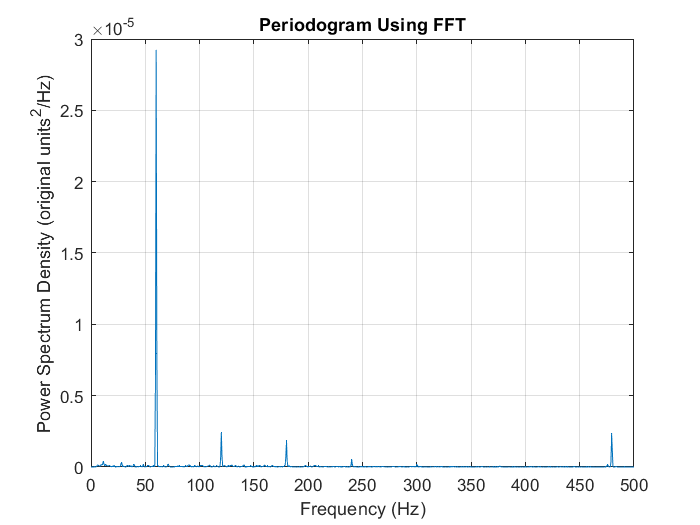

% Power spectrum
Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(EMG_base); % Length of signal
t = (0:L-1)*T;    

% Apply Hanning window to meet the circularity assumption of FFT
EMG_base_w = hann(L).*EMG_base;

% FFT command
Y = fft(EMG_base_w);

% power spectrum
P2 = (abs(Y).^2)/(L*Fs);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;

figure
plot(f,P1)
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum Density (original units^2/Hz)')

An equivalent native Matlab command to get PSD is this one:

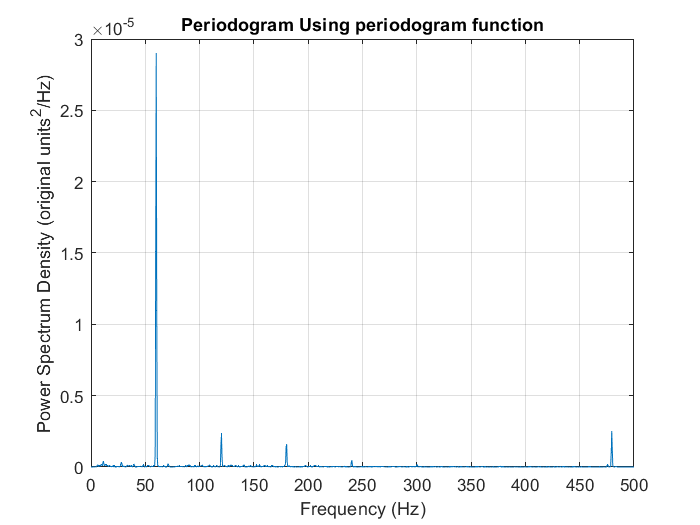

[p,f] = periodogram(EMG_base_w,[],[],Fs);

plot(f,p)
grid on
title('Periodogram Using periodogram function')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum Density (original units^2/Hz)')

### 3) Filtering

Alternating current in the United States and several other countries oscillates at a frequency of 60 Hz. Those oscillations often corrupt measurements and have to be subtracted. Luckily for us, Matlab already has [a tutorial on this topic](https://www.mathworks.com/help/signal/ug/remove-the-60-hz-hum-from-a-signal.html).

The specification for the Butterworth notch filter to liminate the 60 Hz noise using a Butterworth notch filter. Use `designfilt` to design the filter. The width of the notch is defined by the 59 to 61 Hz frequency interval. The filter removes at least half the power of the frequency components lying in that range.

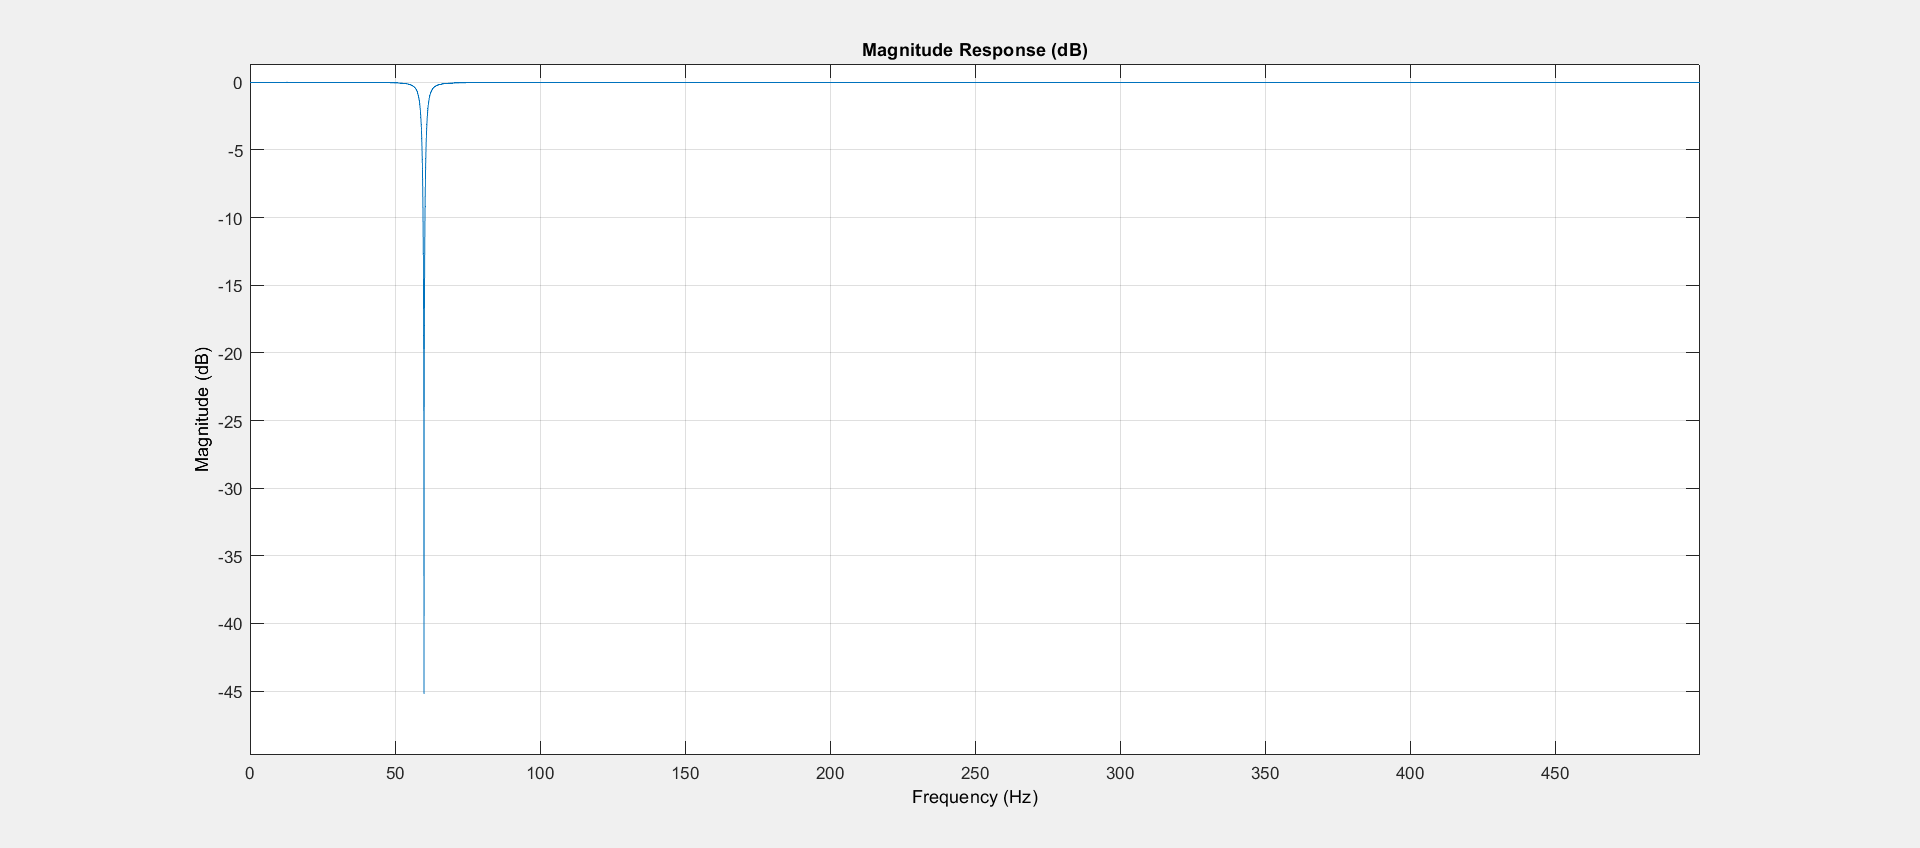

d1 = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',59,'HalfPowerFrequency2',61, ...
               'DesignMethod','butter','SampleRate',Fs);
           
fvtool(d1,'Fs',Fs)    

Apply the filter:

EMG_base_filt = filtfilt(d1,EMG_base)

EMG_base_filt =     0.0110
   -0.0036
    0.0019
   -0.0133
   -0.0046
   -0.0178
   -0.0073
   -0.0126
   -0.0075
   -0.0049



L = length(EMG_base); % Length of signal

[p_filt,f] = periodogram(hann(L).*EMG_base_filt,[],[],Fs); % Apply Hanning window to meet the circularity assumption of FFT
[p,f] = periodogram(hann(L).*EMG_base,[],[],Fs);

figure
subplot(1,2,1)
plot(f,p)
hold

Current plot held


plot(f,p_filt)
grid on
title('Periodogram Using periodogram function')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum Density (original units^2/Hz)')
legend('raw', 'filtered')

subplot(1,2,2)
plot(t, EMG_base)
hold

Current plot held


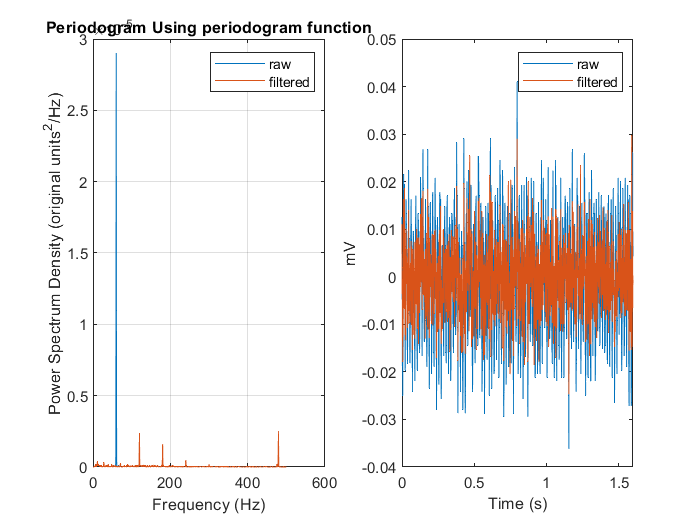

plot(t,EMG_base_filt)
xlabel('Time (s)')
ylabel('mV')
legend('raw', 'filtered')

#### Remove harmonincs (120, 180, 240 Hz) from the EMG signal by applying a notch filter at each frequency. 

EMG_filt = notchFilter_60Hz_harmonics(EMG_base,Fs);

L = length(EMG_base); % Length of signal

[p_filt,f] = periodogram(hann(L).*EMG_filt,[],[],Fs); % Apply Hanning window to meet the circularity assumption of FFT
[p,f] = periodogram(hann(L).*EMG_base,[],[],Fs);

figure
subplot(1,2,1)
plot(f,p)
hold

Current plot held


plot(f,p_filt)
grid on
title('Periodogram Using periodogram function')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum Density (original units^2/Hz)')
legend('raw', 'filtered')

subplot(1,2,2)
plot(t, EMG_base)
hold

Current plot held


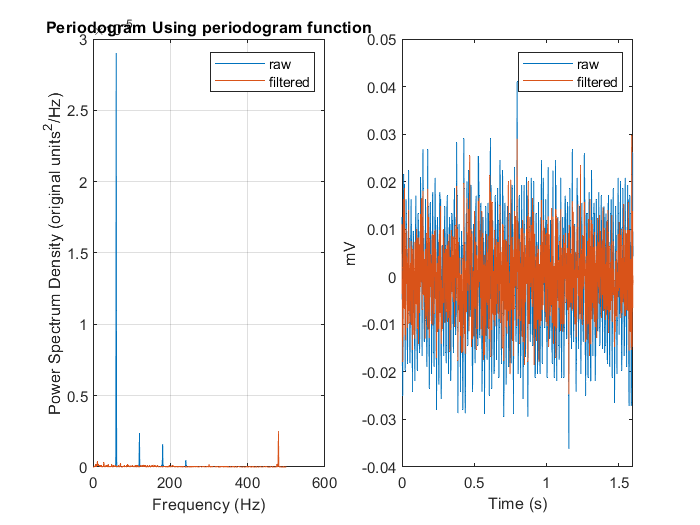

plot(t,EMG_base_filt)
xlabel('Time (s)')
ylabel('mV')
legend('raw', 'filtered')

#### Filter all EMG signal

EMG_filt = notchFilter_60Hz_harmonics(EMG_1_raw_off,Fs);

L = length(EMG_1_raw_off); % Length of signal
t = 1/Fs:1/Fs:length(EMG_1_raw)/Fs

t =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500



[p_filt,f] = periodogram(hann(L).*EMG_filt,[],[],Fs);
[p,f] = periodogram(hann(L).*EMG_1_raw_off,[],[],Fs);

figure
subplot(1,2,1)
plot(f,p)
hold

Current plot held


plot(f,p_filt)
grid on
title('Periodogram Using periodogram function')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum Density (original units^2/Hz)')
legend('raw', 'filtered')

subplot(1,2,2)
plot(t, EMG_1_raw_off)
hold

Current plot held


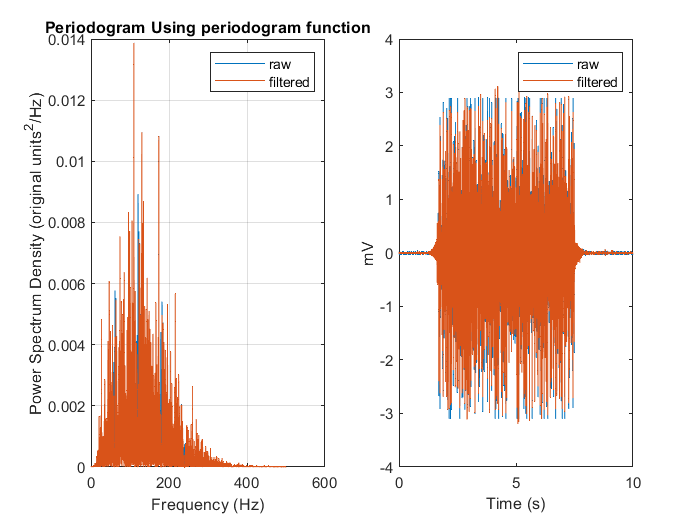

plot(t,EMG_filt)
xlabel('Time (s)')
ylabel('mV')
legend('raw', 'filtered')

#### Filter all EMG signal - forward filter only

EMG_filt = notchFilter_60Hz_harmonics_forward(EMG_1_raw_off,Fs);

L = length(EMG_1_raw_off); % Length of signal
t = 1/Fs:1/Fs:length(EMG_1_raw)/Fs

t =     0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500



[p_filt,f] = periodogram(hann(L).*EMG_filt,[],[],Fs);
[p,f] = periodogram(hann(L).*EMG_1_raw_off,[],[],Fs);

figure
subplot(1,2,1)
plot(f,p)
hold

Current plot held


plot(f,p_filt)
grid on
title('Periodogram Using periodogram function')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum Density (original units^2/Hz)')
legend('raw', 'filtered')

subplot(1,2,2)
plot(t, EMG_1_raw_off)
hold

Current plot held


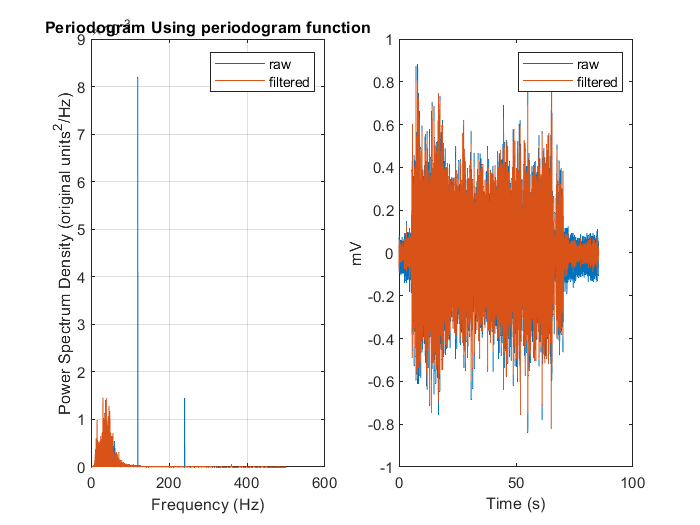

plot(t,EMG_filt)
xlabel('Time (s)')
ylabel('mV')
legend('raw', 'filtered')

### 4) Onset detection

Better on non-filtered or forward-fitered signal

% Rectify signal
EMG_filt_rect = abs(EMG_filt)

EMG_filt_rect =     0.0031
    0.0245
    0.0227
    0.0079
    0.0135
    0.0115
    0.0536
    0.0758
    0.0157
    0.0209



% moving window average with 50 ms
EMG_filt_rect_mw = movmean(EMG_filt_rect,50)

EMG_filt_rect_mw =     0.0271
    0.0272
    0.0272
    0.0269
    0.0262
    0.0257
    0.0250
    0.0256
    0.0267
    0.0270



% find first value of moving average signal that surpasses threshold
% voltage
threshold = 0.1

threshold = 0.1000

onset = find(EMG_filt_rect_mw>threshold,1)

onset = 5466


figure
plot(EMG_filt_rect)
hold

Current plot held


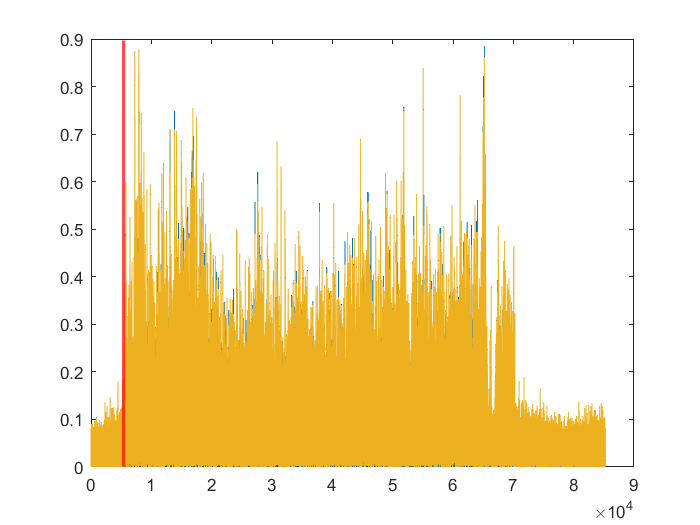

plot(EMG_filt_rect_mw)
xline(onset,'r','linewidth',2)
plot(abs(EMG_1_raw_off))

### 5) Root mean square calculation

% this line of code calculates 
EMG_filt_rms = sqrt(movmean(EMG_filt.^ 2, 50));

figure
plot(t,EMG_filt)
hold

Current plot held


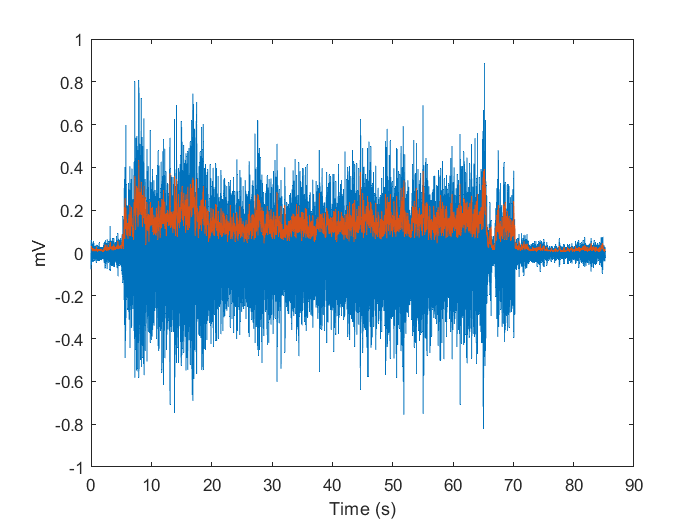

plot(t,EMG_filt_rms)

xlabel('Time (s)')
ylabel('mV')

## 6) Flexion-extension EMG

Import EMG data and prepare for analysis

data = readtable('Carl_1');

Fs = 1000

Fs = 1000

EMG_1_raw = (data.Var1)/4000*3;
plot(EMG_1_raw)

% Remove NaN's from the end of the data
EMG_1_raw = rmmissing(EMG_1_raw)

% remove offset
offset = mean(EMG_1_raw)
EMG_1_raw_off = EMG_1_raw-offset

plot(EMG_1_raw_off)

Import Gotiometer data

Using the default settings for goniometer within the analogue set up dialog box, +/- 4000 counts equals +/- 180 degrees angle. e.g. an ASCII value of +3000 equates to an angle of (3000/4000)*180 Degrees = + 135 degrees. The data collection was such that more negative angle indicates flexion

elbow_ang = data.Var2/4000*180;

elbow_ang =  -115.6950
 -115.6950
 -115.4250
 -115.6950
 -115.0650
 -115.4250
 -115.4250
 -115.0650
 -114.9300
 -114.9300


elbow_ang = rmmissing(elbow_ang); % remove Nan values
Fs_g = 50 % 50 Hz

Fs_g = 200

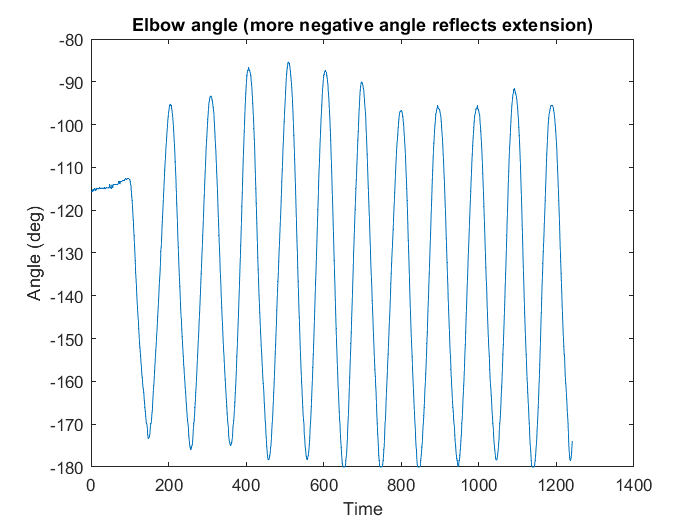


figure
plot(elbow_ang)
title('Elbow angle (more negative angle reflects flexion)')
xlabel('Sample')
ylabel('Angle (deg)')

Filter EMG - remove the AC interference and harmonics

EMG_filt = notchFilter_60Hz_harmonics(EMG_1_raw_off,Fs);

figure
plot(EMG_1_raw_off)
hold
plot(EMG_filt)

% RMS
EMG_filt_rms = sqrt(movmean(EMG_filt.^ 2, 100));
plot(EMG_filt_rms)

Find peak flexion and peak extension times

[PeakExt_a,PeakExt_s] = findpeaks(elbow_ang,'MinPeakProminence',50)
[PeakFlex_a,PeakFlex_s] = findpeaks(-elbow_ang,'MinPeakProminence',50)

figure
subplot(211)
hold on

for i = 1:10
    plot(EMG_filt_rms(PeakExt_s(i)*20:PeakExt_s(i+1)*20))
end
title('EMG RMS')
xlabel('Sample')
ylabel('mV')

subplot(212)
hold
for i = 1:10
    plot(-elbow_ang(PeakExt_s(i):PeakExt_s(i+1)))
end
annotation(gcf,'textarrow',[0.15 0.15],...
    [0.37 0.43],'String',{'Flexion'});
annotation(gcf,'textarrow',[0.15 0.15],...
    [0.23 0.16],'String',{'Extension'});
title('Elbow angle')
xlabel('Sample')
ylabel('Angle (deg)')


% Time-normalize the data for averging - same as in gait cycle ..



t_emg = 1/Fs:1/Fs:length(EMG_1_raw)/Fs

Resample joint angle at 1000 Hz

t = 1/Fs_g:1/Fs_g:length(elbow_ang)/Fs_g

Y = resample(elbow_ang,t,t_emg,'spline')

## 7) Fatigue detection

### Import EMG data and prepare for analysis

data = readtable('Carl_2');

Fs = 1000

Fs = 1000

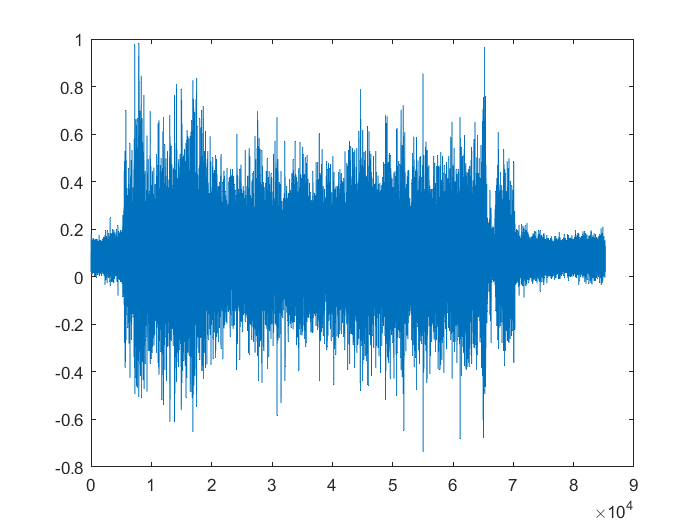

EMG_1_raw = (data.Var1)/4000*3;
plot(EMG_1_raw)


% Remove NaN's from the end of the data
EMG_1_raw = rmmissing(EMG_1_raw)

EMG_1_raw =     0.0983
    0.1268
    0.1260
    0.1102
    0.1147
    0.0892
    0.0450
    0.0203
    0.0825
    0.1245



% remove offset
offset = mean(EMG_1_raw)

offset = 0.1014

EMG_1_raw_off = EMG_1_raw-offset

EMG_1_raw_off =    -0.0032
    0.0253
    0.0246
    0.0088
    0.0133
   -0.0122
   -0.0564
   -0.0812
   -0.0189
    0.0231


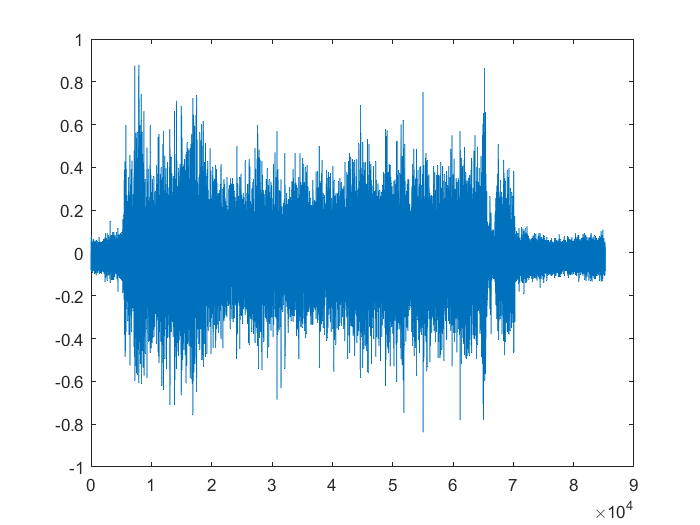


plot(EMG_1_raw_off)

### Import Gotiometer data

Using the default settings for goniometer within the analogue set up dialog box, +/- 4000 counts equals +/- 180 degrees angle. e.g. an ASCII value of +3000 equates to an angle of (3000/4000)*180 Degrees = + 135 degrees. The data collection was such that more negative angle indicates flexion

elbow_ang = data.Var2/4000*180;
elbow_ang = rmmissing(elbow_ang); % remove Nan values
Fs_g = 50 % 50 Hz

Fs_g = 50

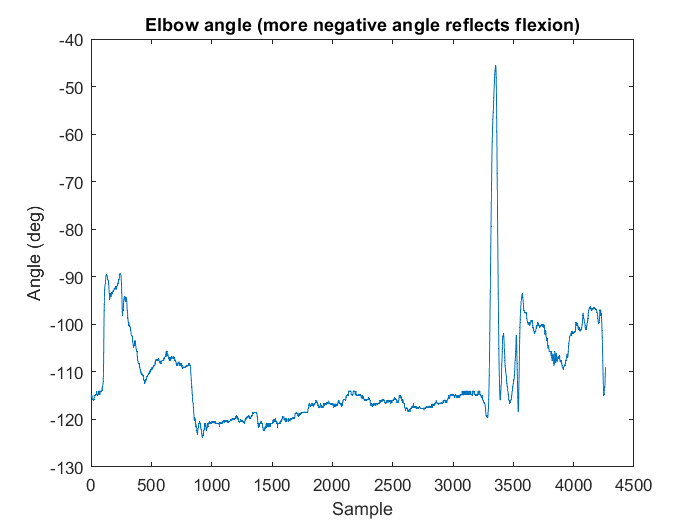


figure
plot(elbow_ang)
title('Elbow angle (more negative angle reflects flexion)')
xlabel('Sample')
ylabel('Angle (deg)')

### Filter EMG remove the AC interference and harmonics

EMG_filt = notchFilter_60Hz_harmonics(EMG_1_raw_off,Fs);

figure
plot(EMG_1_raw_off)
hold

Current plot held


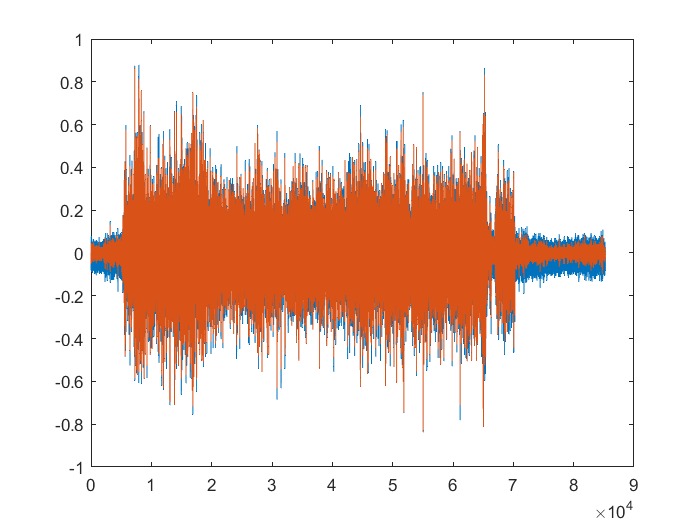

plot(EMG_filt)

### Find changes of the median power of power spectral density due to fatigue

Power spectral density estimatiion during the early (pre) and late segment (post) of the isometric hold. The duration of each segment is 2 s and they were found using visual inspection of the joint angles

Fs = 1000;
L = 2001; % Length of signal

[p_pre,f] = periodogram(hann(L).*EMG_filt(20140:22140),[],[],Fs);
[p_post,f] = periodogram(hann(L).*EMG_filt(62000:64000),[],[],Fs);

figure
subplot(1,2,1)
plot(f,p_pre)
hold

Current plot held


plot(f,p_post)
grid on
title('Periodogram Using periodogram function')
xlabel('Frequency (Hz)')
ylabel('Power Spectrum Density (original units^2/Hz)')
legend('raw', 'filtered')

subplot(1,2,2)
plot(EMG_1_raw(20140:22140))
hold

Current plot held


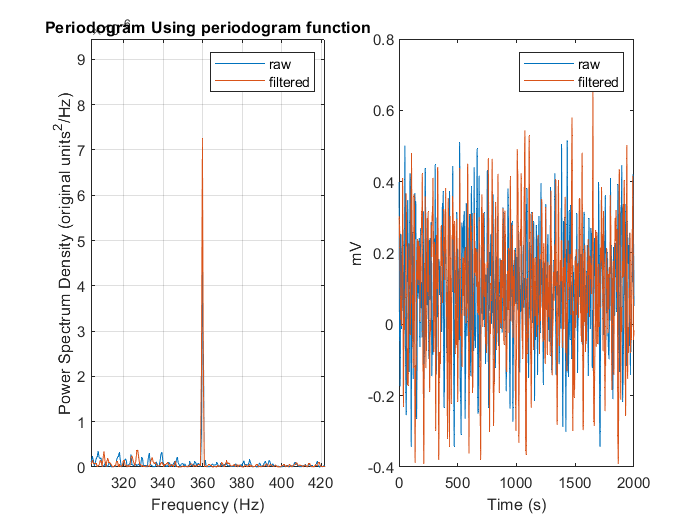

plot(EMG_1_raw(62000:64000))
xlabel('Time (s)')
ylabel('mV')
legend('raw', 'filtered')

Estimate Median Frequency during the early and late segments of the isometric hold

medFreq_pre = medfreq(p_pre,f)
medFreq_post = medfreq(p_post,f)
